## 1. Map of LCOA with solar and no curtailment. 

clearvars
load('SP_nocurt')
for i=1:height(SP_nocurt.unique_loc)
    split_loc=strsplit(SP_nocurt.unique_loc(i),"_");
    Lat(i)=str2double(split_loc(1));
    Lon(i)=str2double(split_loc(2));
end
aveLCOA=log10(mean(SP_nocurt.LCOA_byLoc,2)/1000);
Solar_Nocurt_Map=figure;
s = geoscatter(Lat,Lon,60,aveLCOA,"Marker",'.');
geolimits([min(Lat)-0.5 max(Lat)+0.5],[min(Lon) max(Lon)-2])
colormap(flip(plasma))
c = colorbar('TickLabels',["1000" "1250" "1600" "2000" "2500" "3200" "4000" "5000"],'Ticks',[0,0.097,0.204,0.301,0.4,0.505,0.602,0.7])

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0.2038 1.3688]
    FontSize: 9
    Position: [0.8290 0.1105 0.0381 0.8152]
       Units: 'normalized'

  Show all properties


c.Label.String = "LCOA ($ tonne^{-1})";
clim([0 0.7])
c.Label.FontSize = 14;
c.Label.FontWeight = "bold";
set(gca,'FontSize',14)
gx = gca;
gx.Scalebar.Visible = "off";
gx.LatitudeLabel.String = ''

gx =   GeographicAxes with properties:

     Basemap: 'streets-light'
    Position: [0.1130 0.1227 0.6735 0.8023]
       Units: 'normalized'

  Show all properties


gx.LongitudeLabel.String = ''

gx =   GeographicAxes with properties:

     Basemap: 'streets-light'
    Position: [0.1130 0.1100 0.6735 0.8150]
       Units: 'normalized'

  Show all properties


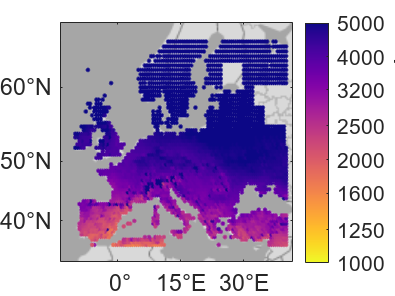

grid off
geobasemap darkwater
exportgraphics(Solar_Nocurt_Map,'Solar NoCurt Map.png','Resolution',1000)

## 2. Maps of LCOA and fraction curtailment with solar and curtailment.

clearvars
load('SP_curt')
for i=1:height(SP_curt.unique_loc)
    split_loc=strsplit(SP_curt.unique_loc(i),"_");
    Lat(i)=str2double(split_loc(1));
    Lon(i)=str2double(split_loc(2));
end
aveLCOA=log10(mean(SP_curt.LCOA_byLoc,2)/1000);
Solar_Curt_Map=figure;
s = geoscatter(Lat,Lon,60,aveLCOA,"Marker",'.');
geolimits([min(Lat)-0.5 max(Lat)+0.5],[min(Lon) max(Lon)-2])
colormap(flip(plasma))
c = colorbar('TickLabels',["1000" "1250" "1600" "2000" "2500" "3200" "4000" "5000"],'Ticks',[0,0.097,0.204,0.301,0.4,0.505,0.602,0.7])

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0.0339 0.9332]
    FontSize: 9
    Position: [0.8290 0.1105 0.0381 0.8152]
       Units: 'normalized'

  Show all properties


c.Label.String = "LCOA ($ tonne^{-1})";
clim([0 0.7])
c.Label.FontSize = 14;
c.Label.FontWeight = "bold";
set(gca,'FontSize',14)
gx = gca;
gx.Scalebar.Visible = "off";
gx.LatitudeLabel.String = ''

gx =   GeographicAxes with properties:

     Basemap: 'streets-light'
    Position: [0.1130 0.1227 0.6735 0.8023]
       Units: 'normalized'

  Show all properties


gx.LongitudeLabel.String = ''

gx =   GeographicAxes with properties:

     Basemap: 'streets-light'
    Position: [0.1130 0.1100 0.6735 0.8150]
       Units: 'normalized'

  Show all properties


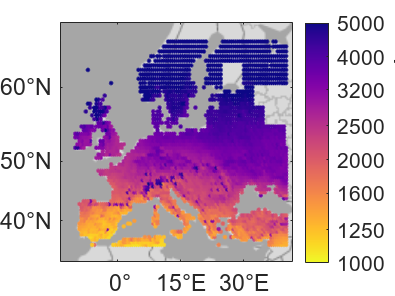

grid off
geobasemap darkwater
exportgraphics(Solar_Curt_Map,'Solar Curt Map.png','Resolution',1000)


load('PinkHeatmap')
for i=1:height(SP_curt.unique_loc)
    split_loc=strsplit(SP_curt.unique_loc(i),"_");
    Lat(i)=str2double(split_loc(1));
    Lon(i)=str2double(split_loc(2));
end
aveCurt=mean(SP_curt.curtailment_byLoc,2);
Solar_FractCurt_Map = figure;
s = geoscatter (Lat,Lon,60,aveCurt,"Marker",'.');
geolimits([min(Lat)-0.5 max(Lat)+0.5],[min(Lon) max(Lon)-2])
cmap = (spring);
colormap(cmap)
c = colorbar('TickLabels',[ "20%" "30%" "40%" "50%" "60%" "70%"],'Ticks',[0.2,0.3,0.4,0.5,0.6,0.7])

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0.2369 0.7573]
    FontSize: 9
    Position: [0.8290 0.1105 0.0381 0.8152]
       Units: 'normalized'

  Show all properties


c.Label.String="Percent Curtailment";
c.Label.FontSize = 14;
c.Label.FontWeight = "bold";
clim([0.2 0.7])
set(gca,'FontSize',14)
gx = gca;
gx.Scalebar.Visible = "off";
gx.LatitudeLabel.String = ''

gx =   GeographicAxes with properties:

     Basemap: 'streets-light'
    Position: [0.1130 0.1227 0.6735 0.8023]
       Units: 'normalized'

  Show all properties


gx.LongitudeLabel.String = ''

gx =   GeographicAxes with properties:

     Basemap: 'streets-light'
    Position: [0.1130 0.1100 0.6735 0.8150]
       Units: 'normalized'

  Show all properties


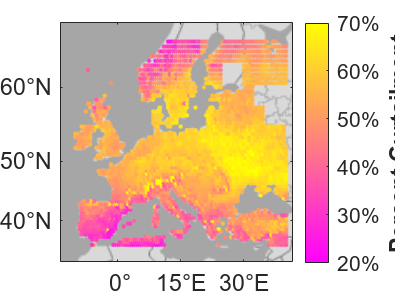

grid off
geobasemap darkwater
exportgraphics(Solar_FractCurt_Map,'Solar Fraction Curtailment Map.png','Resolution',1000);

## 3. Maps of LCOA and fraction of curtailment with solar energy and ramping of the HB process. 

clearvars
load('SP_ramp')
for i=1:height(SP_ramp.unique_loc)
    split_loc=strsplit(SP_ramp.unique_loc(i),"_");
    Lat(i)=str2double(split_loc(1));
    Lon(i)=str2double(split_loc(2));
end
aveLCOA=log10(mean(SP_ramp.LCOA_byLoc,2)/1000);
Solar_Ramp_Map=figure;
s = geoscatter(Lat,Lon,60,aveLCOA,"Marker",'.');
geolimits([min(Lat)-0.5 max(Lat)+0.5],[min(Lon) max(Lon)-2])
colormap(flip(plasma))
c = colorbar('TickLabels',["1000" "1250" "1600" "2000" "2500" "3200" "4000" "5000"],'Ticks',[0,0.097,0.204,0.301,0.4,0.505,0.602,0.7])

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [-0.0713 0.8187]
    FontSize: 9
    Position: [0.8290 0.1105 0.0381 0.8152]
       Units: 'normalized'

  Show all properties


c.Label.String = "LCOA ($ tonne^{-1})";
clim([0 0.7])
c.Label.FontSize = 14;
c.Label.FontWeight = "bold";
set(gca,'FontSize',14)
gx = gca;
gx.Scalebar.Visible = "off";
gx.LatitudeLabel.String = ''

gx =   GeographicAxes with properties:

     Basemap: 'streets-light'
    Position: [0.1130 0.1227 0.6735 0.8023]
       Units: 'normalized'

  Show all properties


gx.LongitudeLabel.String = ''

gx =   GeographicAxes with properties:

     Basemap: 'streets-light'
    Position: [0.1130 0.1100 0.6735 0.8150]
       Units: 'normalized'

  Show all properties


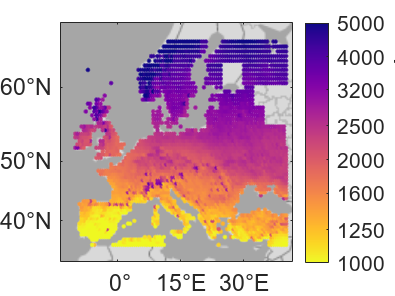

grid off
geobasemap darkwater
exportgraphics(Solar_Ramp_Map,'Solar Ramp Map.png','Resolution',1000)


load('PinkHeatmap')
for i=1:height(SP_ramp.unique_loc)
    split_loc=strsplit(SP_ramp.unique_loc(i),"_");
    Lat(i)=str2double(split_loc(1));
    Lon(i)=str2double(split_loc(2));
end
aveCurt=mean(SP_ramp.curtailment_byLoc,2);
Solar_Ramp_Curt_Map = figure;
s = geoscatter (Lat,Lon,60,aveCurt,"Marker",'.');
geolimits([min(Lat)-0.5 max(Lat)+0.5],[min(Lon) max(Lon)-2])
cmap = flip(PinkHeatmap);
colormap(cmap)
c = colorbar('TickLabels',["10%" "20%" "30%" "40%" "50%" "60%"],'Ticks',[0.1,0.2,0.3,0.4,0.5,0.6])

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0.0672 0.7008]
    FontSize: 9
    Position: [0.8290 0.1105 0.0381 0.8152]
       Units: 'normalized'

  Show all properties


c.Label.String="Percent Curtailment";
c.Label.FontSize = 14;
c.Label.FontWeight = "bold";
clim([0.1 0.6])
set(gca,'FontSize',14)
gx = gca;
gx.Scalebar.Visible = "off";
gx.LatitudeLabel.String = ''

gx =   GeographicAxes with properties:

     Basemap: 'streets-light'
    Position: [0.1130 0.1227 0.6735 0.8023]
       Units: 'normalized'

  Show all properties


gx.LongitudeLabel.String = ''

gx =   GeographicAxes with properties:

     Basemap: 'streets-light'
    Position: [0.1130 0.1100 0.6735 0.8150]
       Units: 'normalized'

  Show all properties


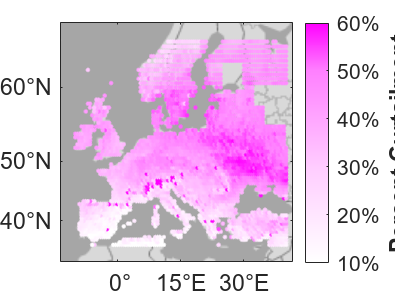

grid off
geobasemap darkwater
exportgraphics(Solar_Ramp_Curt_Map,'Solar Ramp Curt Map.png','Resolution',1000);

## 4. Map of LCOA with wind and no curtailment. 

clearvars
load('WP_nocurt')
for i=1:height(WP_nocurt.unique_loc)
    split_loc=strsplit(WP_nocurt.unique_loc(i),"_");
    Lat(i)=str2double(split_loc(1));
    Lon(i)=str2double(split_loc(2));
end
aveLCOA=log10(mean(WP_nocurt.LCOA_byLoc,2)/1000);
Wind_Nocurt_Map=figure;
s = geoscatter(Lat,Lon,60,aveLCOA,"Marker",'.');
geolimits([35 65.5],[-10 38])
colormap(flip(plasma))
c = colorbar('TickLabels',["1000" "1250" "1600" "2000" "2500" "3200" "4000" "5000"],'Ticks',[0,0.097,0.204,0.301,0.4,0.505,0.602,0.7])

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0.0487 1.4201]
    FontSize: 9
    Position: [0.8290 0.1105 0.0381 0.8152]
       Units: 'normalized'

  Show all properties


c.Label.String = "LCOA ($ tonne^{-1})";
clim([0 0.7])
c.Label.FontSize = 14;
c.Label.FontWeight = "bold";
set(gca,'FontSize',14)
gx = gca;
gx.Scalebar.Visible = "off";
gx.LatitudeLabel.String = ''

gx =   GeographicAxes with properties:

     Basemap: 'streets-light'
    Position: [0.1130 0.1227 0.6735 0.8023]
       Units: 'normalized'

  Show all properties


gx.LongitudeLabel.String = ''

gx =   GeographicAxes with properties:

     Basemap: 'streets-light'
    Position: [0.1130 0.1100 0.6735 0.8150]
       Units: 'normalized'

  Show all properties


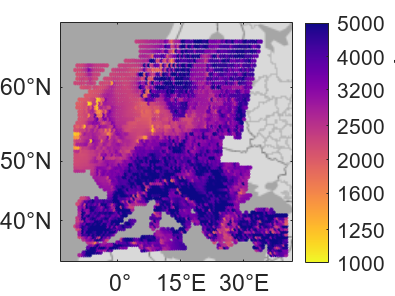

grid off
geobasemap darkwater
exportgraphics(Wind_Nocurt_Map,'Wind Nocurt Map.png','Resolution',1000)

## 5. Maps of LCOA and fraction curtailment with wind and curtailment.

clearvars
load('WP_curt')
for i=1:height(WP_curt.unique_loc)
    split_loc=strsplit(WP_curt.unique_loc(i),"_");
    Lat(i)=str2double(split_loc(1));
    Lon(i)=str2double(split_loc(2));
end
aveLCOA=log10(mean(WP_curt.LCOA_byLoc/1000,2));
Wind_Curt_Map=figure;
s = geoscatter(Lat,Lon,60,aveLCOA,"Marker",'.');
geolimits([35 65.5],[-10 38])
colormap(flip(plasma))
c = colorbar('TickLabels',["1000" "1250" "1600" "2000" "2500" "3200" "4000" "5000"],'Ticks',[0,0.097,0.204,0.301,0.4,0.505,0.602,0.7])

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [-0.0961 1.3625]
    FontSize: 9
    Position: [0.8290 0.1105 0.0381 0.8152]
       Units: 'normalized'

  Show all properties


c.Label.String = "LCOA ($ tonne^{-1})";
clim([0 0.7])
c.Label.FontSize = 14;
c.Label.FontWeight = "bold";
set(gca,'FontSize',14)
gx = gca;
gx.Scalebar.Visible = "off";
gx.LatitudeLabel.String = ''

gx =   GeographicAxes with properties:

     Basemap: 'streets-light'
    Position: [0.1130 0.1227 0.6735 0.8023]
       Units: 'normalized'

  Show all properties


gx.LongitudeLabel.String = ''

gx =   GeographicAxes with properties:

     Basemap: 'streets-light'
    Position: [0.1130 0.1100 0.6735 0.8150]
       Units: 'normalized'

  Show all properties


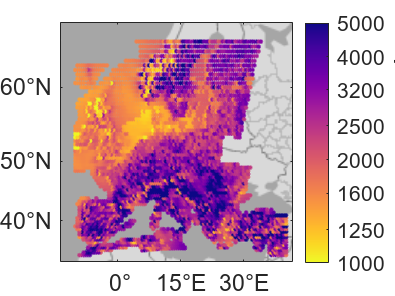

grid off
geobasemap darkwater
exportgraphics(Wind_Curt_Map,'Wind Curt Map.png','Resolution',1000)


load('PinkHeatmap')
for i=1:height(WP_curt.unique_loc)
    split_loc=strsplit(WP_curt.unique_loc(i),"_");
    Lat(i)=str2double(split_loc(1));
    Lon(i)=str2double(split_loc(2));
end
aveCurt=mean(WP_curt.curt_byLoc,1)';
Wind_FractCurt_Map = figure;
s = geoscatter (Lat,Lon,60,aveCurt,"Marker",'.');
geolimits([35 65.5],[-10 38])
cmap = (spring);
colormap(cmap)
c = colorbar('TickLabels',["10%" "20%" "30%" "40%" "50%" "60%"],'Ticks',[0.1,0.2,0.3,0.4,0.5,0.6])

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0.0056 0.7065]
    FontSize: 9
    Position: [0.8290 0.1105 0.0381 0.8152]
       Units: 'normalized'

  Show all properties


c.Label.String = "Percent Curtailment";
clim([0.1 0.6])
c.Label.FontSize = 14;
c.Label.FontWeight = "bold";
set(gca,'FontSize',14)
gx = gca;
gx.Scalebar.Visible = "off";
gx.LatitudeLabel.String = ''

gx =   GeographicAxes with properties:

     Basemap: 'streets-light'
    Position: [0.1130 0.1227 0.6735 0.8023]
       Units: 'normalized'

  Show all properties


gx.LongitudeLabel.String = ''

gx =   GeographicAxes with properties:

     Basemap: 'streets-light'
    Position: [0.1130 0.1100 0.6735 0.8150]
       Units: 'normalized'

  Show all properties


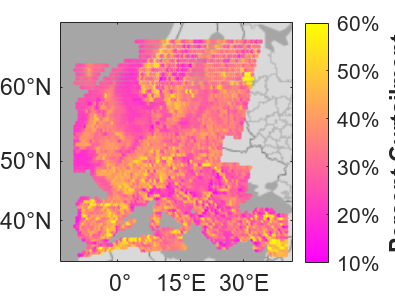

grid off
geobasemap darkwater
exportgraphics(Wind_FractCurt_Map,'Wind Fraction Curtailment Map.png','Resolution',1000);

## 6. Maps of LCOA and fraction of curtailment with wind energy and ramping of the HB process. 

clearvars
load('WP_ramp')
for i=1:height(WP_ramp.unique_loc)
    split_loc=strsplit(WP_ramp.unique_loc(i),"_");
    Lat(i)=str2double(split_loc(1));
    Lon(i)=str2double(split_loc(2));
end
aveLCOA=log10(mean(WP_ramp.LCOA_byLoc,2)/1000);
Wind_Ramp_Map=figure;
s = geoscatter(Lat,Lon,60,aveLCOA,"Marker",'.');
geolimits([35 65.5],[-10 38])
colormap(flip(plasma))
c = colorbar('TickLabels',["1000" "1250" "1600" "2000" "2500" "3200" "4000" "5000"],'Ticks',[0,0.097,0.204,0.301,0.4,0.505,0.602,0.7])

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [-0.2177 1.3462]
    FontSize: 9
    Position: [0.8290 0.1105 0.0381 0.8152]
       Units: 'normalized'

  Show all properties


c.Label.String = "LCOA ($ tonne^{-1})";
clim([0 0.7])
c.Label.FontSize = 14;
c.Label.FontWeight = "bold";
set(gca,'FontSize',14)
gx = gca;
gx.Scalebar.Visible = "off";
gx.LatitudeLabel.String = ''

gx =   GeographicAxes with properties:

     Basemap: 'streets-light'
    Position: [0.1130 0.1227 0.6735 0.8023]
       Units: 'normalized'

  Show all properties


gx.LongitudeLabel.String = ''

gx =   GeographicAxes with properties:

     Basemap: 'streets-light'
    Position: [0.1130 0.1100 0.6735 0.8150]
       Units: 'normalized'

  Show all properties


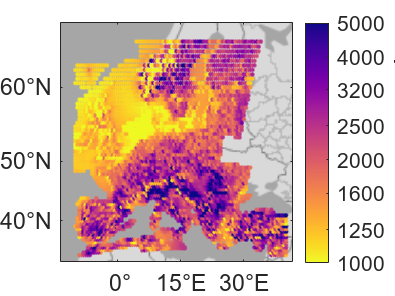

grid off
geobasemap darkwater
exportgraphics(Wind_Ramp_Map,'Wind Ramp Map.pdf','Resolution',1000)


load('PinkHeatmap')
for i=1:height(WP_ramp.unique_loc)
    split_loc=strsplit(WP_ramp.unique_loc(i),"_");
    Lat(i)=str2double(split_loc(1));
    Lon(i)=str2double(split_loc(2));
end
aveCurt=mean(WP_ramp.curtailment_byLoc,2);
Wind_Ramp_Curt_Map = figure;
s = geoscatter (Lat,Lon,60,aveCurt,"Marker",'.');
geolimits([35 65.5],[-10 38])
cmap = flip(PinkHeatmap);
colormap(cmap)
c = colorbar('TickLabels',["10%" "20%" "30%" "40%" "50%" "60%"],'Ticks',[0.1,0.2,0.3,0.4,0.5,0.6])

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0.0053 0.5849]
    FontSize: 9
    Position: [0.8290 0.1105 0.0381 0.8152]
       Units: 'normalized'

  Show all properties


c.Label.String="Percent Curtailment";
c.Label.FontSize = 14;
c.Label.FontWeight = "bold";
clim([0.1 0.8])
set(gca,'FontSize',14)
gx = gca;
gx.Scalebar.Visible = "off";
gx.LatitudeLabel.String = ''

gx =   GeographicAxes with properties:

     Basemap: 'streets-light'
    Position: [0.1130 0.1227 0.6735 0.8023]
       Units: 'normalized'

  Show all properties


gx.LongitudeLabel.String = ''

gx =   GeographicAxes with properties:

     Basemap: 'streets-light'
    Position: [0.1130 0.1100 0.6735 0.8150]
       Units: 'normalized'

  Show all properties


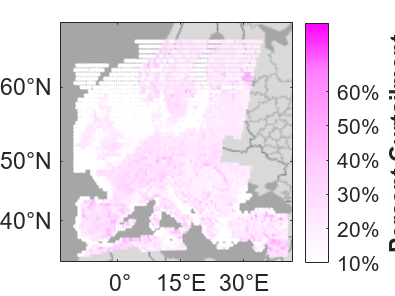

grid off
geobasemap darkwater
exportgraphics(Wind_Ramp_Curt_Map,'Wind Ramp Curt Map.png','Resolution',1000);

## 7. Maps of LCOA, fraction curtailment, and percent solar energy when combining solar and wind energy. 

clearvars
load('CP_curt')
for i=1:height(CP_curt.unique_loc)
    split_loc=strsplit(CP_curt.unique_loc(i),"_");
    Lat(i)=str2double(split_loc(1));
    Lon(i)=str2double(split_loc(2));
end
aveLCOA=log10(mean(CP_curt.LCOA_byLoc,2)/1000);
Combined_Curt_Map=figure;
s = geoscatter(Lat,Lon,60,aveLCOA,"Marker",'.');
geolimits([35 65.5],[-10 38])
colormap(flip(plasma))
c = colorbar('TickLabels',["1000" "1250" "1600" "2000" "2500" "3200" "4000" "5000"],'Ticks',[0,0.097,0.204,0.301,0.4,0.505,0.602,0.7])

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [-0.1113 0.7780]
    FontSize: 9
    Position: [0.8290 0.1105 0.0381 0.8152]
       Units: 'normalized'

  Show all properties


c.Label.String = "LCOA ($ tonne^{-1})";
clim([0.0 0.7])
c.Label.FontSize = 14;
c.Label.FontWeight = "bold";
set(gca,'FontSize',14)
gx = gca;
gx.Scalebar.Visible = "off";
gx.LatitudeLabel.String = ''

gx =   GeographicAxes with properties:

     Basemap: 'streets-light'
    Position: [0.1130 0.1227 0.6735 0.8023]
       Units: 'normalized'

  Show all properties


gx.LongitudeLabel.String = ''

gx =   GeographicAxes with properties:

     Basemap: 'streets-light'
    Position: [0.1130 0.1100 0.6735 0.8150]
       Units: 'normalized'

  Show all properties


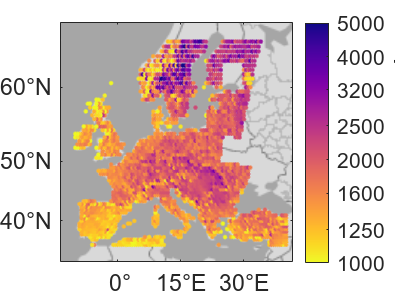

grid off
geobasemap darkwater
exportgraphics(Combined_Curt_Map,'Combined Curt Map.png','Resolution',1000)


load('PinkHeatmap')
for i=1:height(CP_curt.unique_loc)
    split_loc=strsplit(CP_curt.unique_loc(i),"_");
    Lat(i)=str2double(split_loc(1));
    Lon(i)=str2double(split_loc(2));
end
aveFS=(mean(CP_curt.curtailment_byLoc,2));
Combined_Curtailment = figure;
s = geoscatter(Lat,Lon,60,aveFS,"Marker",".");
geolimits([35 65.5],[-10 38])
cmap =(spring);
colormap(cmap)
c = colorbar('Ticks',[0.1 0.2 0.3 0.4 0.5],'TickLabels',["10%" "20%" "30%" "40%" "50%"])

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0.1140 0.6165]
    FontSize: 9
    Position: [0.8290 0.1105 0.0381 0.8152]
       Units: 'normalized'

  Show all properties


c.Label.String="Percent Curtailment";
c.Label.FontSize = 14;
c.Label.FontWeight = "bold";
clim([0.1 0.5])
set(gca,'FontSize',14)
gx = gca;
gx.Scalebar.Visible = "off";
gx.LatitudeLabel.String = ''

gx =   GeographicAxes with properties:

     Basemap: 'streets-light'
    Position: [0.1130 0.1227 0.6735 0.8023]
       Units: 'normalized'

  Show all properties


gx.LongitudeLabel.String = ''

gx =   GeographicAxes with properties:

     Basemap: 'streets-light'
    Position: [0.1130 0.1100 0.6735 0.8150]
       Units: 'normalized'

  Show all properties


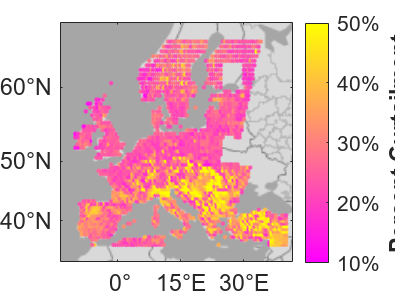

grid off
geobasemap darkwater
exportgraphics(Combined_Curtailment,'Combined Curtailment Map.png','Resolution',1000);


load('YellowBluemap')
for i=1:height(CP_curt.unique_loc)
    split_loc=strsplit(CP_curt.unique_loc(i),"_");
    Lat(i)=str2double(split_loc(1));
    Lon(i)=str2double(split_loc(2));
end
aveFS=(mean(CP_curt.fractSolar_byLoc,2));
Combined_Curt_FractSolar = figure;
s = geoscatter(Lat,Lon,60,aveFS,"MArker",".");
geolimits([35 65.5],[-10 38])
cmap = flip(YellowBluemap);
colormap(cmap)
c = colorbar('Ticks',[0 0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1], 'TickLabels',["0%" "10%" "20%" "30%" "40%" "50%" "60%" "70%" "80%" "90%" "100%"])

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0.0226 1]
    FontSize: 9
    Position: [0.8290 0.1105 0.0381 0.8152]
       Units: 'normalized'

  Show all properties


c.Label.String = "Percentage of Energy from Solar";
clim([0 1])
c.Label.FontSize = 14;
c.Label.FontWeight = "bold";
set(gca,'FontSize',14)
gx = gca;
gx.Scalebar.Visible = "off";
gx.LatitudeLabel.String = ''

gx =   GeographicAxes with properties:

     Basemap: 'streets-light'
    Position: [0.1130 0.1227 0.6735 0.8023]
       Units: 'normalized'

  Show all properties


gx.LongitudeLabel.String = ''

gx =   GeographicAxes with properties:

     Basemap: 'streets-light'
    Position: [0.1130 0.1100 0.6735 0.8150]
       Units: 'normalized'

  Show all properties


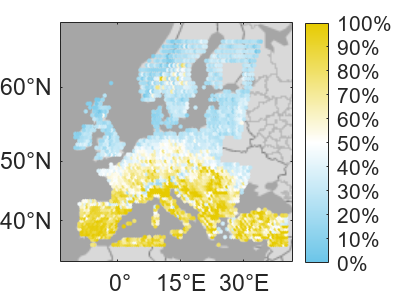

grid off
geobasemap darkwater
exportgraphics(Combined_Curt_FractSolar,'Combined Curt FractSolar Map.png','Resolution',1000);